%% Baltttiefe nach Schmitz, Vgls Pasch S.206
lamda_A=7;              %% Schnellaufzahl           [1] lambda=2*pi*n*r/v_0
R=50;                   %% Rotor-radius             [m]
r=linspace(0,50,100)    %% Position auf dem Rotor   [m]

r =          0    0.5051    1.0101    1.5152    2.0202    2.5253    3.0303    3.5354    4.0404    4.5455    5.0505    5.5556    6.0606    6.5657    7.0707    7.5758    8.0808    8.5859    9.0909    9.5960   10.1010   10.6061   11.1111   11.6162   12.1212   12.6263   13.1313   13.6364   14.1414   14.6465   15.1515   15.6566   16.1616   16.6667   17.1717   17.6768   18.1818   18.6869   19.1919   19.6970   20.2020   20.7071   21.2121   21.7172   22.2222   22.7273   23.2323   23.7374   24.2424   24.7475


c_L=1.3;                %%Auftriebsmoment           [1]
z=3;                    %% ANzahl Rotorblätter      [1]

## Blattiefe nach Schmitz

alpha_1=atan(R./(lamda_A.*r));
t_schmitz=16.*pi.*lamda_A.*r./R.*sin(1./3.*alpha_1).^2,

t_schmitz =          0    0.8171    1.4970    2.0501    2.4891    2.8278    3.0802    3.2600    3.3799    3.4513    3.4840    3.4864    3.4655    3.4269    3.3754    3.3144    3.2470    3.1753    3.1012    3.0259    2.9504    2.8755    2.8018    2.7297    2.6594    2.5911    2.5250    2.4611    2.3994    2.3399    2.2826    2.2275    2.1745    2.1235    2.0744    2.0272    1.9818    1.9381    1.8961    1.8556    1.8167    1.7791    1.7430    1.7082    1.6746    1.6422    1.6109    1.5807    1.5515    1.5234


t=t_schmitz.*R/(lamda_A.*z.*c_L);            %% wirkliche Blatttiefe [m]

## plot

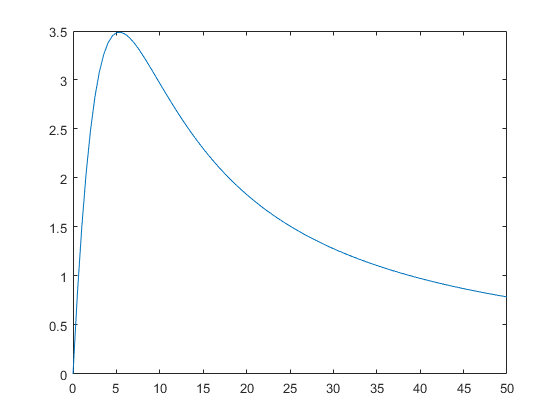

plot(r,t_schmitz)